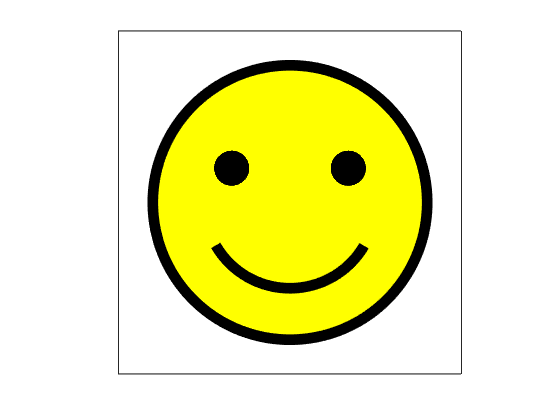

% Idealised image
face_c = [0.5, 0.5];
face_r = 0.4;
eye1_c = [0.33, 0.6];
eye2_c = [0.67, 0.6];
eye_r = 0.05;

% Create raster
Nx = 21;
Ny = 21;
R = 255 * ones(Ny, Nx, 3);

R = drawcircle(R, 1+floor(Nx * face_c(1)), 1+floor(Ny * face_c(2)), floor(Nx * face_r), [0;0;0]);
R = floodfill(R, 10, 10, [255;255;255], [255;255;0]);
for i = 1 : 3
    R(8:9, 7:8, i) = 0;
    R(8:9, 14:15, i) = 0;
    R(14,7,i) = 0;
    R(15,8,i) = 0;
    R(16,9:13,i) = 0;
    R(15,14,i) = 0;
    R(14,15,i) = 0;
end

% Plot idealised image
theta = 0 : pi / 200 : 2 * pi;
x = face_c(1) + face_r * cos(theta);
y = face_c(2) + face_r * sin(theta);
patch(x, y, 'y')
hold on
plot(x, y, color='k', LineWidth=8);

x = eye1_c(1) + eye_r * cos(theta);
y = eye1_c(2) + eye_r * sin(theta);
fill(x, y, 'k');

x = eye2_c(1) + eye_r * cos(theta);
y = eye2_c(2) + eye_r * sin(theta);
fill(x, y, 'k');

theta = deg2rad(210) : pi / 200 : deg2rad(330);
x = 0.5 + 0.25 * cos(theta);
y = 0.5 + 0.25 * sin(theta);
plot(x, y, color='k', LineWidth=8);

hold off

xticks([])
yticks([])
axis equal
box on
axis([0, 1, 0, 1])

exportgraphics(gcf,'../images/idealised_image.png','Resolution',300) 

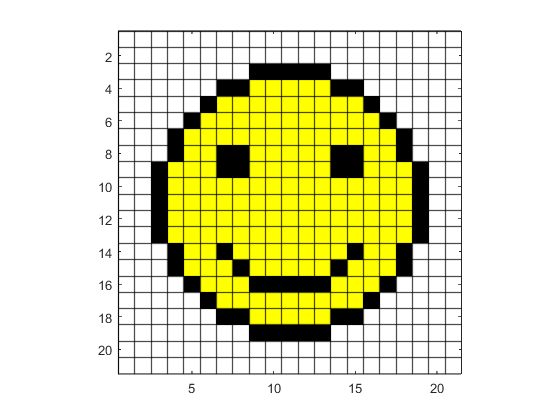


% Plot raster
figure
image(R)
hold on
for row = 1 : 1 : Nx
    xline(row-0.5, Color='k', LineWidth=1);
    yline(row-0.5, Color='k', LineWidth=1);
end
hold off

axis equal
axis([0.5, Nx+0.5, 0.5, Ny+0.5])

exportgraphics(gcf,'../images/raster_image.png','Resolution',300) 

function R = drawcircle(R, cx, cy, r, colour)

D = 5 - 4 * r;
x = r;
y = 0;
while y <= x
    R(cy+y, cx-x, :) = colour;
    R(cy-y, cx+x, :) = colour;
    R(cy-y, cx-x, :) = colour;
    R(cy+x, cx+y, :) = colour;
    R(cy+x, cx-y, :) = colour;
    R(cy-x, cx+y, :) = colour;
    R(cy-x, cx-y, :) = colour;
    R(cy+y, cx+x, :) = colour;

    if D > 0
        D = D - 8 * x + 8 * y + 20;
        x = x - 1;
    else
        D = D + 8 * y + 12;
    end
    y = y + 1;
end

end

function R = floodfill(R, x0, y0, target, replacement)

Q = [ x0, y0 ];
while isempty(Q) == 0
    pixel = Q(end,:);
    Q(end,:) = [];
    if R(pixel(2), pixel(1), 1) == target(1) && ...
            R(pixel(2), pixel(1), 2) == target(2) && ...
            R(pixel(2), pixel(1), 3) == target(3)
        R(pixel(2), pixel(1), :) = replacement;
        Q = [ Q ; 
            pixel(1) + 1, pixel(2) ; 
            pixel(1) - 1, pixel(2) ;
            pixel(1), pixel(2) + 1 ;
            pixel(1), pixel(2) - 1 ];
    end
end

end